# CHW04 - Tensor Decompositions - 401110448 - Mohammad Sadra Hosseini

## Q1.

I define a function called my_cp_als that gets our tensor and initialized factor matrices and gives final factor matrices. first initialize final factor matrices with initial factor matrices, then calculate all three unfolding matrices from our tensor. then use below equation for our final factor matrices respectively and do iterations till convergence


$$U_n = T^{(n)}(U_N \odot U_{N-1}\odot ... \odot U_{n+1}\odot U_{n-1}\odot ... \odot U_1)V^\dagger$$


and V is 


$$V = U_1^T U_1* U_2^2 U_2 * ... * U_{n-1}^TU_{n-1} * U_{n+1}^TU_{n+1}*...*U_N^TU_N$$


## Q2.

2.1

I_is are dimensions of our random tensors and R is the number of components of cp decompositions.

clc, clear,  close all

I1 = 5;
I2 = 5;
I3 = 5;
R = 3;
SNR = [0, 20, 40, 60];

first define an array for saving errors of algorithms. the last dimension of this array describes we want calculate error for 4 algorithms, my cp function, matlab cp function, matlab sd and matlab minf.

for every algorithm we want 30 iterations. in every iteration, first initialize Uorgs using normrnd function with 0 and 1 for two first inputs as mean and variance respectively and then dimension of every Uorg. then construct T tensor from 


$$T = \llbracket{I;U_{org}^{(1)}, U_{org}^{(2)}, U_{org}^{(3)}}\rrbracket$$
 

then for every SNR, first add a noise tensor to T tensor, then re-initialize Us with zero mean and 1 variance from a gaussian distribution. then for every algorithm calculate error. for uncertainty of permutations, i use TMSE function. for adding noise to T tensor i use below equation


$$T_{noisy} = T + \alpha N$$


that alpha calculate by


$$SNR_{dB} = 10 \log_{10} (\frac{||T||_F^2}{\alpha^2||N||_F^2})$$



$$\Rightarrow \alpha = \frac{||T||_F}{10^{\frac{SNR_{dB}}{20}}||N||_F}$$


error_als = zeros(30, length(SNR), 4);
for number = 1 : 30
    T = zeros(I1, I2, I3); 
    Uorg1 = normrnd(0, 1, I1, R);
    Uorg2 = normrnd(0, 1, I2, R);
    Uorg3 = normrnd(0, 1 ,I3, R);
    Uorg = {Uorg1, Uorg2, Uorg3};
     
    for i = 1 : I1
        for j = 1 : I2
            for k = 1 : I3
                t = 0;
                for l = 1 : R
                    t = t + Uorg1(i, l) * Uorg2(j, l) * Uorg3(k, l);
                end
                T(i, j, k) = t;
            end
        end
    end
    
    for i = 1 : numel(SNR)
        N = normrnd(0, 1, I1, I2, I3);
        alpha = fro_norm(T) / (10^(SNR(i) / 20) * fro_norm(N));
        T_noisy = T + alpha * N;
        
        U1_0 = normrnd(0, 1, I1, R);
        U2_0 = normrnd(0, 1, I2, R);
        U3_0 = normrnd(0, 1, I3, R);
        U0 = {U1_0, U2_0, U3_0};
        
        % my als algorithm
        [Uorg1, Uorg2, Uorg3] = my_cp_als(T_noisy, U1_0, U2_0, U3_0);
        my_als = {Uorg1, Uorg2, Uorg3};
    
        % matlab als algorithm 
        matlab_als = cpd_als(T_noisy, U0);
        
        % matlab sd algorithm 
        matlab_sd = cpd3_sd(T_noisy, U0);
        
        % matlab minf algorithm 
        matlab_minf = cpd_minf(T_noisy, U0);
        
        error_als(number, i, 1) = TMSE(Uorg, my_als);
        error_als(number, i, 2) = TMSE(Uorg, matlab_als);
        error_als(number, i, 3) = TMSE(Uorg, matlab_sd);
        error_als(number, i, 4) = TMSE(Uorg, matlab_minf);
    end
end

now we must plot get mean from 30 tensors and plot it versus SNR. 

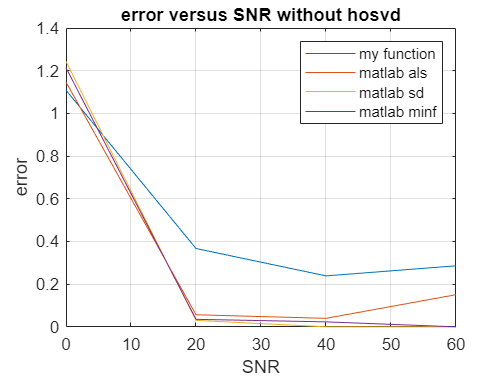

mean_error_als = mean(error_als, 1);

figure;
plot(SNR, mean_error_als(1, :, 1));
hold on;
plot(SNR, mean_error_als(1, :, 2));
hold on;
plot(SNR, mean_error_als(1, :, 3));
hold on;
plot(SNR, mean_error_als(1, :, 4));
xlabel('SNR');
ylabel('error');
title('error versus SNR without hosvd');
legend('my function', 'matlab als', 'matlab sd', 'matlab minf');
grid on;

as we can see from graphs, in low SNR sd function works worse than other algorithms. in middle SNR(about 20) all algorithms work good, but in high SNRs(more than 20) results of sd is better than minf, minf better than matlab's als algorithm and our function works worse than others. we conclude that in general case and particularly in datasets with less noise(pure datasets) sd and minf work great. 

2.2

for this part, i do all of previous part with a little difference. for re-initialze U factor matrices, i use hosvd algorithm.

in this algorithm n-th factor matrix calculate by R leading left singular vectors of unfolding mode-n of our tensor.

error_als_hosvd = zeros(30, length(SNR), 4);
for number = 1 : 30
    T = zeros(I1, I2, I3); 
    Uorg1 = normrnd(0, 1, I1, R);
    Uorg2 = normrnd(0, 1, I2, R);
    Uorg3 = normrnd(0, 1 ,I3, R);
    Uorg = {Uorg1, Uorg2, Uorg3};
     
    for i = 1 : I1
        for j = 1 : I2
            for k = 1 : I3
                t = 0;
                for l = 1 : R
                    t = t + Uorg1(i, l) * Uorg2(j, l) * Uorg3(k, l);
                end
                T(i, j, k) = t;
            end
        end
    end
    
    for i = 1 : numel(SNR)
        N = normrnd(0, 1, I1, I2, I3);
        alpha = fro_norm(T) / (10^(SNR(i) / 20) * fro_norm(N));
        T_noisy = T + alpha * N;
        
        [U1_0, U2_0, U3_0] = hosvd(T_noisy);
        U0 = {U1_0, U2_0, U3_0};
        
        % my als algorithm
        [Uorg1, Uorg2, Uorg3] = my_cp_als(T_noisy, U1_0, U2_0, U3_0);
        my_als = {Uorg1, Uorg2, Uorg3};
    
        % matlab als algorithm 
        matlab_als = cpd_als(T_noisy, U0);
        
        % matlab sd algorithm 
        matlab_sd = cpd3_sd(T_noisy, U0);
        
        % matlab minf algorithm 
        matlab_minf = cpd_minf(T_noisy, U0);
        
        error_als_hosvd(number, i, 1) = TMSE(Uorg, my_als);
        error_als_hosvd(number, i, 2) = TMSE(Uorg, matlab_als);
        error_als_hosvd(number, i, 3) = TMSE(Uorg, matlab_sd);
        error_als_hosvd(number, i, 4) = TMSE(Uorg, matlab_minf);
    end
end       

then plot error versus SNR for this part

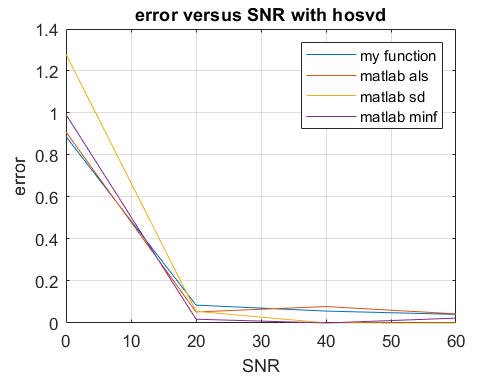

mean_error_als_hosvd = mean(error_als_hosvd, 1);

figure;
plot(SNR, mean_error_als_hosvd(1, :, 1));
hold on;
plot(SNR, mean_error_als_hosvd(1, :, 2));
hold on;
plot(SNR, mean_error_als_hosvd(1, :, 3));
hold on;
plot(SNR, mean_error_als_hosvd(1, :, 4));
xlabel('SNR');
ylabel('error');
title('error versus SNR with hosvd');
legend('my function', 'matlab als', 'matlab sd', 'matlab minf');
grid on;

as we can see from graphs, in less SNRs, sd works worse than others. in high SNRs all of matlab algorithms work better than our function. Also matlab's built-in functions work better when their input come from hosvd's output. It is trivial, because when we use hosvd for inputs, we get close to better convergence.

2.3

this part is like first part, just with a difference in initilizing T using the algorithm in problem.

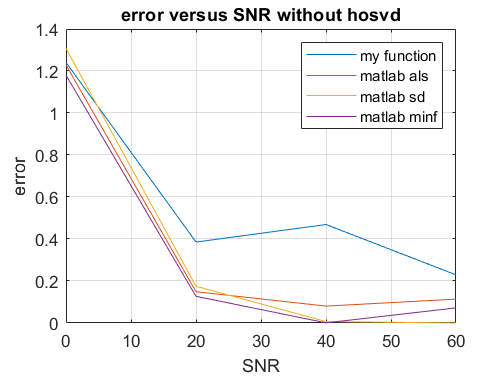

error_als = zeros(30, length(SNR), 4);
for number = 1 : 30
    T = zeros(I1, I2, I3); 
    U11 = normrnd(0, 1, I1, 1);
    v2 = normrnd(0, 1, I1, 1);
    U12 = U11 + 0.5 * v2;
    U13 = normrnd(0, 1, I1, 1);
    U21 = normrnd(0, 1, I2, 1);
    v2 = normrnd(0, 1, I2, 1);
    U22 = U21 + 0.5 * v2;
    U23 = normrnd(0, 1, I2, 1);
    Uorg1 = [U11, U12, U13];
    Uorg2 = [U21, U22, U23];
    Uorg3 = normrnd(0, 1 ,I3, R);
    Uorg = {Uorg1, Uorg2, Uorg3};
     
    for i = 1 : I1
        for j = 1 : I2
            for k = 1 : I3
                t = 0;
                for l = 1 : R
                    t = t + Uorg1(i, l) * Uorg2(j, l) * Uorg3(k, l);
                end
                T(i, j, k) = t;
            end
        end
    end
    
    for i = 1 : numel(SNR)
        N = normrnd(0, 1, I1, I2, I3);
        alpha = fro_norm(T) / (10^(SNR(i) / 20) * fro_norm(N));
        T_noisy = T + alpha * N;
        
        U1_0 = normrnd(0, 1, I1, R);
        U2_0 = normrnd(0, 1, I2, R);
        U3_0 = normrnd(0, 1, I3, R);
        U0 = {U1_0, U2_0, U3_0};
        
        % my als algorithm
        [Uorg1, Uorg2, Uorg3] = my_cp_als(T_noisy, U1_0, U2_0, U3_0);
        my_als = {Uorg1, Uorg2, Uorg3};
    
        % matlab als algorithm 
        matlab_als = cpd_als(T_noisy, U0);
        
        % matlab sd algorithm 
        matlab_sd = cpd3_sd(T_noisy, U0);
        
        % matlab minf algorithm 
        matlab_minf = cpd_minf(T_noisy, U0);
        
        error_als(number, i, 1) = TMSE(Uorg, my_als);
        error_als(number, i, 2) = TMSE(Uorg, matlab_als);
        error_als(number, i, 3) = TMSE(Uorg, matlab_sd);
        error_als(number, i, 4) = TMSE(Uorg, matlab_minf);
    end
end

mean_error_als = mean(error_als, 1);

figure;
plot(SNR, mean_error_als(1, :, 1));
hold on;
plot(SNR, mean_error_als(1, :, 2));
hold on;
plot(SNR, mean_error_als(1, :, 3));
hold on;
plot(SNR, mean_error_als(1, :, 4));
xlabel('SNR');
ylabel('error');
title('error versus SNR without hosvd');
legend('my function', 'matlab als', 'matlab sd', 'matlab minf');
grid on;

the most important change in this graph against part one graph is a horizental shift in error. this happens because Uorg1's columns and Uorg2's columns are dependent together(we don't like this). but still in low SNRs sd function works bad and also matlab's built in functions work better in high SNRs. sd is the best choice in high SNRs.

2.4

this part is like second part, just with a difference in initilizing T using the algorithm in problem.

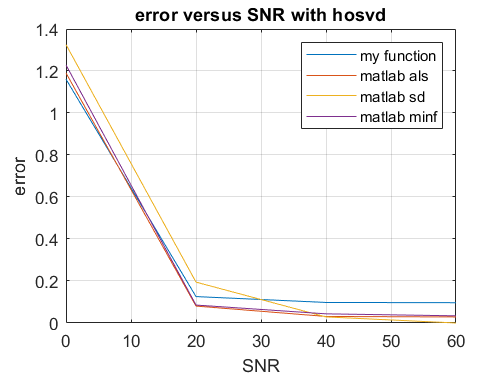

error_als_hosvd = zeros(30, length(SNR), 4);
for number = 1 : 30
    T = zeros(I1, I2, I3); 
    U11 = normrnd(0, 1, I1, 1);
    v2 = normrnd(0, 1, I1, 1);
    U12 = U11 + 0.5 * v2;
    U13 = normrnd(0, 1, I1, 1);
    U21 = normrnd(0, 1, I2, 1);
    v2 = normrnd(0, 1, I2, 1);
    U22 = U21 + 0.5 * v2;
    U23 = normrnd(0, 1, I2, 1);
    Uorg1 = [U11, U12, U13];
    Uorg2 = [U21, U22, U23];
    Uorg3 = normrnd(0, 1 ,I3, R);
    Uorg = {Uorg1, Uorg2, Uorg3}; 

    for i = 1 : I1
        for j = 1 : I2
            for k = 1 : I3
                t = 0;
                for l = 1 : R
                    t = t + Uorg1(i, l) * Uorg2(j, l) * Uorg3(k, l);
                end
                T(i, j, k) = t;
            end
        end
    end
    
    for i = 1 : numel(SNR)
        N = normrnd(0, 1, I1, I2, I3);
        alpha = fro_norm(T) / (10^(SNR(i) / 20) * fro_norm(N));
        T_noisy = T + alpha * N;
        
        [U1_0, U2_0, U3_0] = hosvd(T_noisy);
        U0 = {U1_0, U2_0, U3_0};
        
        % my als algorithm
        [Uorg1, Uorg2, Uorg3] = my_cp_als(T_noisy, U1_0, U2_0, U3_0);
        my_als = {Uorg1, Uorg2, Uorg3};
    
        % matlab als algorithm 
        matlab_als = cpd_als(T_noisy, U0);
        
        % matlab sd algorithm 
        matlab_sd = cpd3_sd(T_noisy, U0);
        
        % matlab minf algorithm 
        matlab_minf = cpd_minf(T_noisy, U0);
        
        error_als_hosvd(number, i, 1) = TMSE(Uorg, my_als);
        error_als_hosvd(number, i, 2) = TMSE(Uorg, matlab_als);
        error_als_hosvd(number, i, 3) = TMSE(Uorg, matlab_sd);
        error_als_hosvd(number, i, 4) = TMSE(Uorg, matlab_minf);
    end
end

mean_error_als_hosvd = mean(error_als_hosvd, 1);

figure;
plot(SNR, mean_error_als_hosvd(1, :, 1));
hold on;
plot(SNR, mean_error_als_hosvd(1, :, 2));
hold on;
plot(SNR, mean_error_als_hosvd(1, :, 3));
hold on;
plot(SNR, mean_error_als_hosvd(1, :, 4));
xlabel('SNR');
ylabel('error');
title('error versus SNR with hosvd');
legend('my function', 'matlab als', 'matlab sd', 'matlab minf');
grid on;

as expectation, in this part, because of initializing Us by hosvd, results have less error than previous part. everything is like part2 except one thing, that is more error because columns of U01 and U02 are dependent.

## Q3.

3.1

first load dataset

clc, clear, close all
load('amino.mat');

we have an unfolded matrix of our dataset. first convert this matrix to tensor. then initialize U_0s with normal distribution. then apply my_cp_als, cpd_als, cpd3_sd and cpd_minf respectively. then plot them versus excitation.

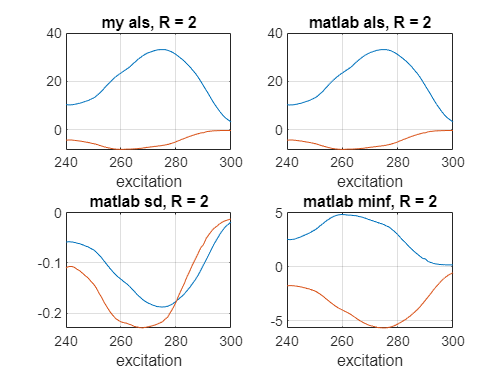

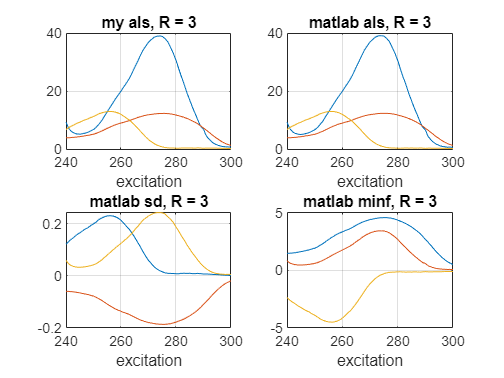

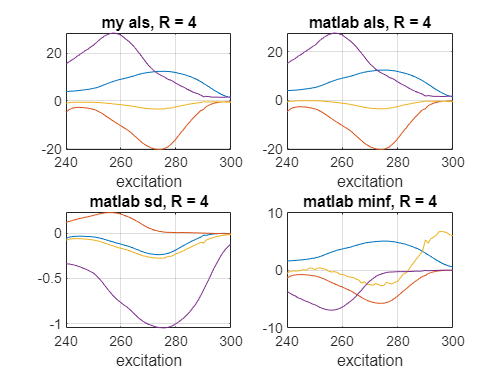

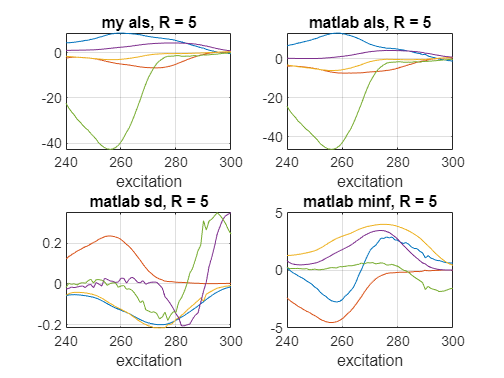

I1 = DimX(1);
I2 = DimX(2);
I3 = DimX(3);

T = zeros(I1, I2, I3);
for i = 1 : 61
    T(:, :, i) = X(:, ((i - 1) * 201 + 1) : (i * 201));
end

R = [2, 3, 4, 5];
for r = 1 : numel(R)
    U1_0 = normrnd(0, 1, I1, R(r));
    U2_0 = normrnd(0, 1, I2, R(r));
    U3_0 = normrnd(0, 1, I3, R(r));
    U0 = {U1_0, U2_0, U3_0};

    % my als function 
    [Uorg1, Uorg2, Uorg3] = my_cp_als(T, U1_0, U2_0, U3_0);
    tensorized = {Uorg1, Uorg2, Uorg3};
    my_als{r} = tensorized;
        
    % matlab als function
    matlab_als{r} = cpd_als(T, U0);

    % matlab sd function
    matlab_sd{r} = cpd3_sd(T, U0);

    % matlab minf function
    matlab_minf{r} = cpd_minf(T, U0);
end

title_string = {'my als', 'matlab als', 'matlab sd', 'matlab minf'};

excitation_interval = [240 : 300];
for i = 1 : 4
    figure; 
    subplot(2, 2, 1);
    U = my_als{i}{3};
    for k = 1 : R(i)
        plot(excitation_interval, U(:, k));
        hold on;
    end
    grid on;
    title({sprintf('%s, R = %d', string(title_string(1)), R(i))});
    xlabel('excitation');
   
    subplot(2, 2, 2);
    U = matlab_als{i}{3};
    for k = 1 : R(i)
        plot(excitation_interval, U(:, k));
        hold on;
    end
    grid on;
    title({sprintf('%s, R = %d', string(title_string(2)), R(i))});
    xlabel('excitation');

    subplot(2, 2, 3);
    U = matlab_sd{i}{3};
    for k = 1 : R(i)
        plot(excitation_interval, U(:, k));
        hold on;
    end
    grid on;
    title({sprintf('%s, R = %d', string(title_string(3)), R(i))});
    xlabel('excitation');

    subplot(2, 2, 4);
    U = matlab_minf{i}{3};
    for k = 1 : R(i)
        plot(excitation_interval, U(:, k));
        hold on;
    end
    grid on;
    title({sprintf('%s, R = %d', string(title_string(4)), R(i))});
    xlabel('excitation');
end

as we can see from graphs, in R = 2, all algorithms detect both of components(but als algorithms almost detect one component because another one has less amplitude). in R = 3, all algorithms detect all three components. in R = 4, all algorithms detect all four components, but actualy in sd algorithm one component has more amplitude than others(and als algorithms almost detect three components). for R = 5, all algorithms almost detect 5 component(but als algorithms almost detect one important component exactly like R = 1 and R = 4). an important point is that we have 3 components actualy.

3.2

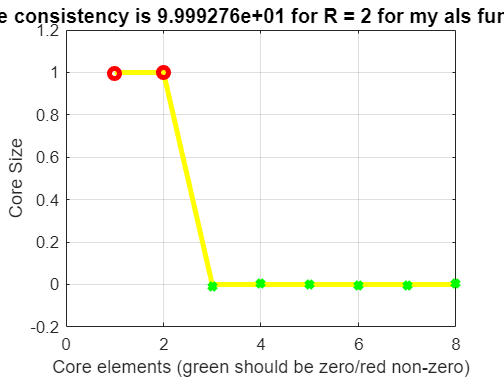

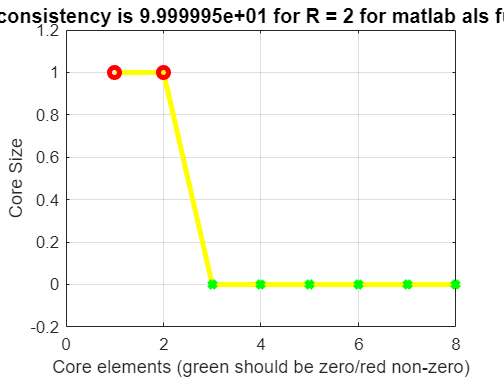

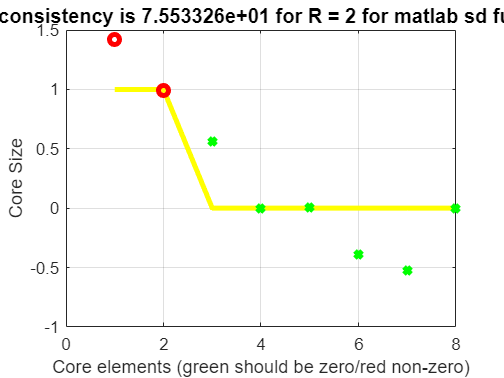

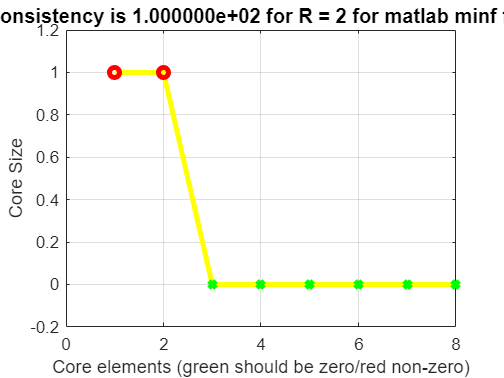

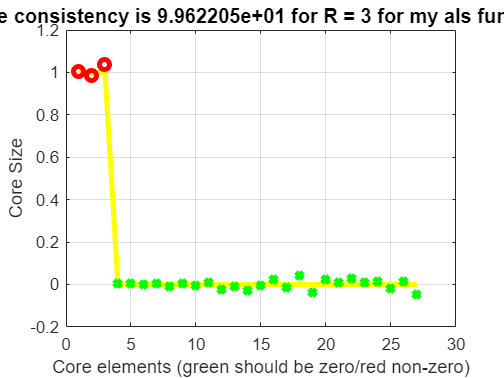

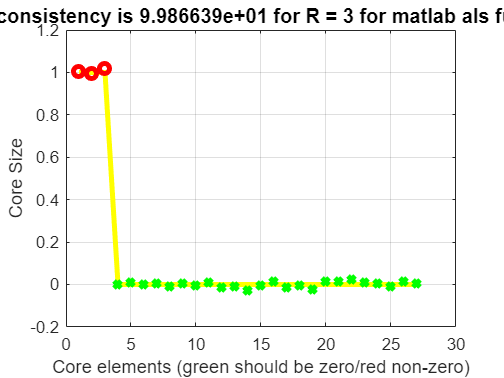

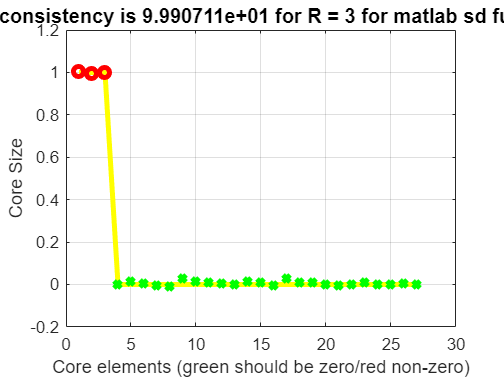

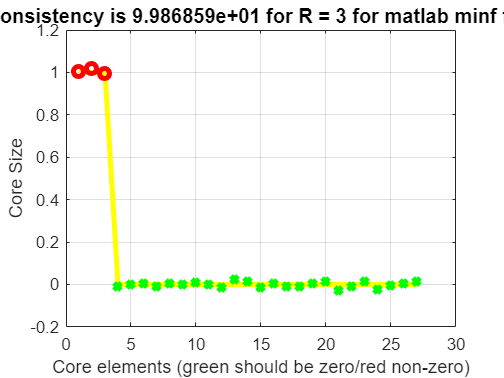

for i = 1 : length(R)
    figure;
    [consistency, ~, ~, ~] = corcond(T, my_als{i}, [], 1);
    title({sprintf('core consistency is %d for R = %d for my als function', consistency, R(i))});
    grid on;

    figure;
    [consistency, ~, ~, ~] = corcond(T, matlab_als{i}, [], 1);
    title({sprintf('core consistency is %d for R = %d for matlab als function', consistency, R(i))});
    grid on;

    figure;
    [consistency, ~, ~, ~] = corcond(T, matlab_sd{i}, [], 1);
    title({sprintf('core consistency is %d for R = %d for matlab sd function', consistency, R(i))});
    grid on;

    figure;
    [consistency, ~, ~, ~] = corcond(T, matlab_minf{i}, [], 1);
    title({sprintf('core consistency is %d for R = %d for matlab minf function', consistency, R(i))});
    grid on;
end

as a search i had on internet i find this :

"CPD can alternatively be written as 


$$\mathcal{X} \approx \mathcal{\phi} \times_1 A \times_2 B \times_3 C$$


where $\times_n
$ denotes tensor-matrix product in mode n and $\phi
$is a core identity tensor where position i = j = k has value 1 and 0 elsewhere for an ideal CPD, its core tensor will always be an identity tensor $\phi
$. This led to the concept of corcondia defined as


$$CORCONDIA = 100 \times (1 - (\frac{||\phi - \mathcal{X}||^2}{||\phi||^2}))$$


Corcondia can help determine the number of components R for the CPD by assessing the interaction between modes A, B and C to the tensor X. If the number of components R is suitable for the model, and the interactions are appropriate, the core tensor $\mathcal{G}$ should closely resemble $\phi
$ and yield a value close to 100 percent in corcondia. Corcondia can straightforwardly be extended to the n-way tensor, making this a powerful approach for CPD."

as above discussion, and also the results of corcondia function's graphs in R = 2, except sd algorithm, all algorithms have great core consistency(very close to 100 percent).

In R = 3, all algorithms have great core consistency(almost 100 percent).

for R = 4 and R = 5, core consistency will decrease. so we understand that CP decomposition works great for R = 2 and R = 3, and works bad for R = 4 and R = 5.